# Rastersiation Examples

[Link to lecture notes](https://jonshiach.github.io/graphics-book/files/5.0_Rasterisation.html)

### Reading and ploting an image file in MATLAB

Download image file

urlwrite("https://github.com/jonshiach/graphics-book/raw/main/MATLAB/cavendish.jpg", "Cavendish.jpg");

Read image file

img = imread('cavendish.jpg');
[Ny, Nx, Ncolours] = size(img)

Ny = 600

Nx = 800

Ncolours = 3

Plot image file

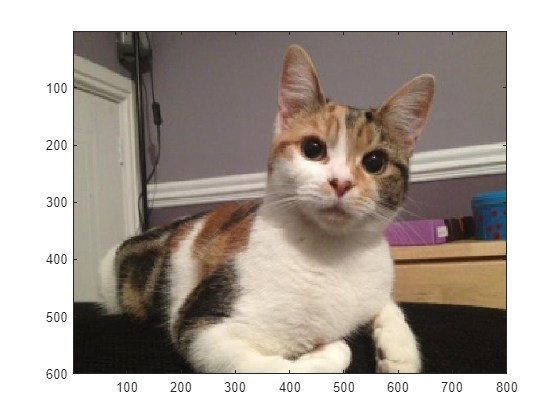

image(img)

### Change pixels to black or white

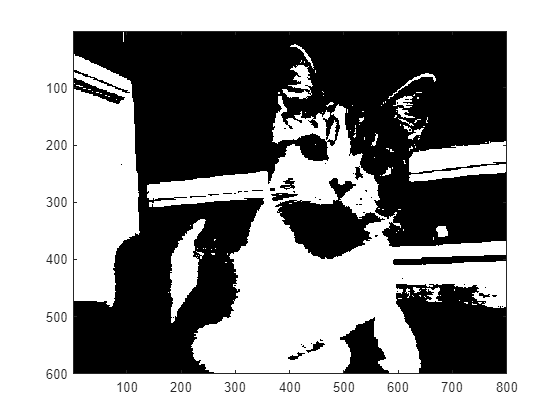

% Reshape array to an (num pixels x 3) array
img_bw = reshape(img, [Nx * Ny, Ncolours]);

% Calculate average colour of each pixel
avg = mean(img_bw, 2);

% Change the colour of each pixel to black or white
img_bw(avg <= 128, :) = 0;
img_bw(avg > 128, :) = 255;

% Reshape image array back to the original shape
img_bw = reshape(img_bw, [Ny, Nx, Ncolours]);

% Plot image array
image(img_bw)

### Example 38 - Bresenham's algorithm

Use the basic Bresenham's algorithm to determine the co-ordinates of the pixels on the straight line joining the two pixels with co-ordinates $(2, 2)$ and $(7, 5)$

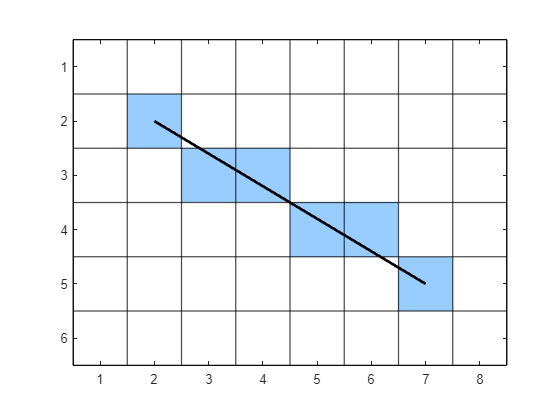

clear

% Define line
x0 = 2;
y0 = 2;
x1 = 7;
y1 = 5;
colour = [153 ; 204 ; 255] / 255;

% Initialise raster array
Nx = 8;
Ny = 6;
img = 255 * ones(Ny, Nx, 3);

% Draw line
img = bresenham(img, x0, y0, x1, y1, colour);

% Plot raster
figure
image(img)
pixelgrid(img)
hold on
plot([x0, x1], [y0, y1], 'k', LineWidth=2)
hold off
axis equal tight

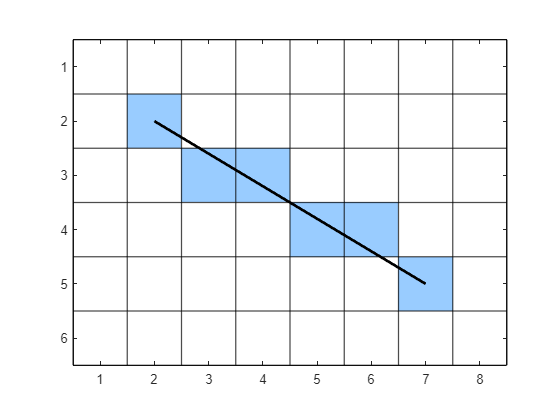

clear

% Define line
x0 = 2;
y0 = 2;
x1 = 7;
y1 = 5;
colour = [153 ; 204 ; 255] / 255;

% Initialise raster array
Nx = 8;
Ny = 6;
img = 255 * ones(Ny, Nx, 3);

% Draw line
img = bresenham(img, x0, y0, x1, y1, colour);

% Plot raster
figure
image(img)
pixelgrid(img)
hold on
plot([x0, x1], [y0, y1], 'k', LineWidth=2)
hold off
axis equal tight

### Example 39 - Modified Bresenham algorithm

Use Bresenham’s algorithm for drawing lines in any direction to determine the co-ordinates of the pixels on the lines joining the following points:

(i)    $(1,1)$ and $(5,7)$;

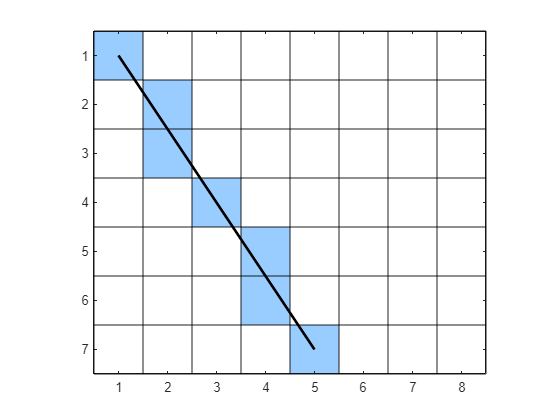

clear

% Define line
x0 = 1;
y0 = 1;
x1 = 5;
y1 = 7;
colour = [153 ; 204 ; 255] / 255;

% Initialise raster array
Nx = 8;
Ny = 7;
img = 255 * ones(Ny, Nx, 3);

% Draw line
img = drawline(img, x0, y0, x1, y1, colour);

% Plot raster
figure
image(img)
pixelgrid(img)
hold on
plot([x0, x1], [y0, y1], 'k', LineWidth=2)
hold off
axis equal tight

(ii)    $(7,2)$ and $(3, 5)$

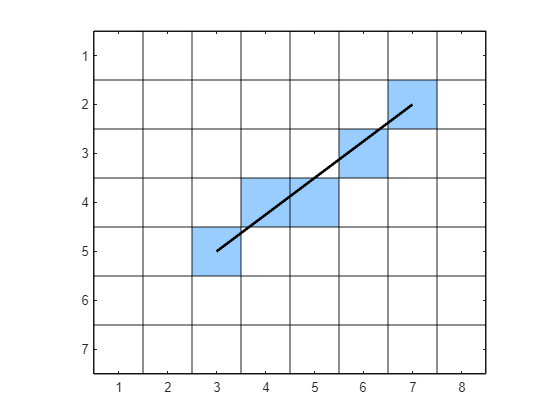

clear

% Define line
x0 = 7;
y0 = 2;
x1 = 3;
y1 = 5;
colour = [153 ; 204 ; 255] / 255;

% Initialise raster array
Nx = 8;
Ny = 7;
img = 255 * ones(Ny, Nx, 3);

% Draw line
img = drawline(img, x0, y0, x1, y1, colour);

% Plot raster
figure
image(img)
pixelgrid(img)
hold on
plot([x0, x1], [y0, y1], 'k', LineWidth=2)
hold off
axis equal tight

### Example 40 - Midpoint algortihm

Use the midpoint algorithm to rasterise a circle centred at (12,12) with radius 10.

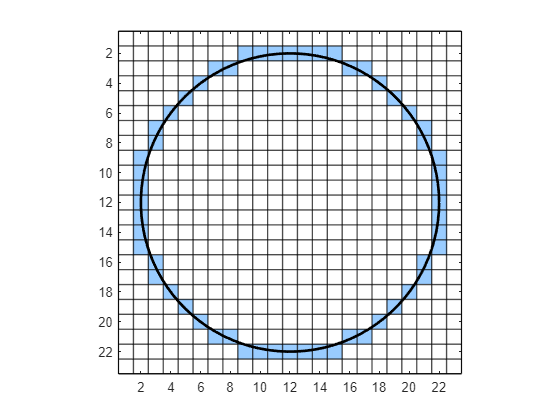

clear

% Define circle
cx = 12;
cy = 12;
r = 10;
colour = [153 ; 204 ; 255] / 255;

% Initialise raster array
Nx = 23;
Ny = 23;
img = 255 * ones(Ny, Nx, 3);

% Draw line
img = drawcircle(img, cx, cy, r, colour);

% Calculate circle
theta = linspace(0, 2 * pi, 100);
x = cx + r * cos(theta);
y = cy + r * sin(theta);

% Plot raster
figure
image(img)
pixelgrid(img)
hold on
plot(x, y, 'k', LineWidth=2)
hold off
axis equal tight
xticks(2 : 2 : 22)

### Example 41 - Flood fill algorithm

Starting with the pixel at (4,4), use the flood fill algorithm to fill in the polygon on the raster below where the target colour is white and the replacement colour is blue.

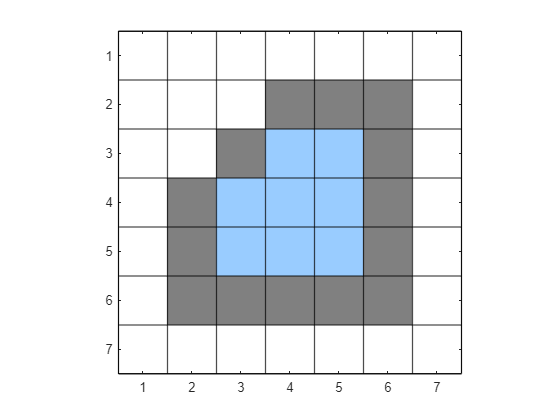

clear

% Define polygon
X = [2, 6, 6, 4, 2];
Y = [6, 6, 2, 2, 4];
border = [128 ; 128 ; 128] / 255;

% Initialise raster array
Nx = 7;
Ny = 7;
img = 255 * ones(Ny, Nx, 3);

% Draw polygon outline
j = length(X);
for i = 1 : length(X)
    img = drawline(img, X(i), Y(i), X(j), Y(j), border);
    j = i;
end

% Fill interior of polygon
x0 = 4;
y0 = 4;
target = [255 ; 255 ; 255];
replacement = [153 ; 204 ; 255] / 255;
img = floodfill(img, x0, y0, target, replacement);

% Plot raster
figure
image(img)
pixelgrid(img)
axis equal tight

### Example 42 - Scanline algorithm

Use the scanline algorithm to draw the polygon defined below

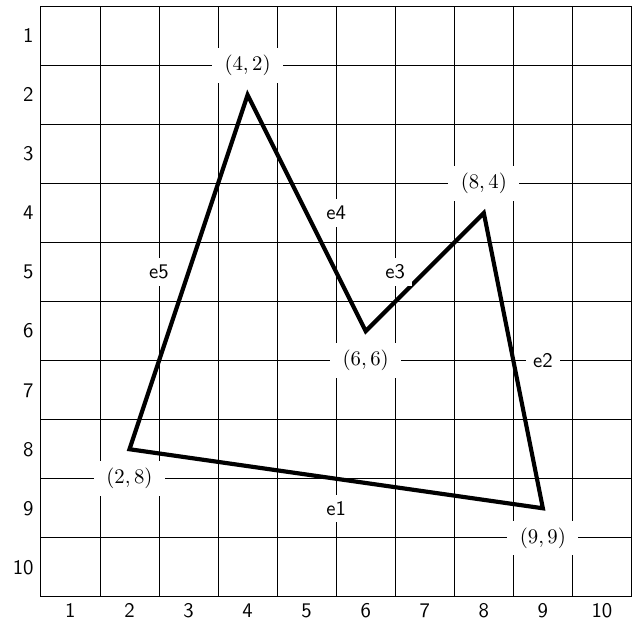

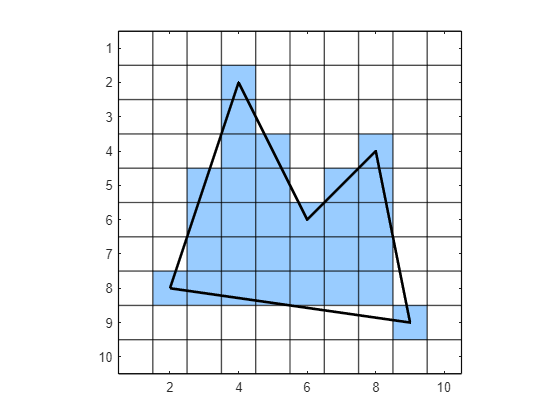

% Define polygon vertices and colour
X = [2, 9, 8, 6, 4];
Y = [8, 9, 4, 6, 2];
colour = [153 ; 204 ; 255] / 255;

% Initialise raster array
Nx = 10;
Ny = 10;
img = ones(Ny, Nx, 3);

% Draw polygon
img = drawpolygon(img, X, Y, colour);

% Plot raster
image(img)
pixelgrid(img)
hold on
plot([X, X(1)], [Y, Y(1)], 'k-', LineWidth=2) 
hold off
axis equal tight

### Antialiasing

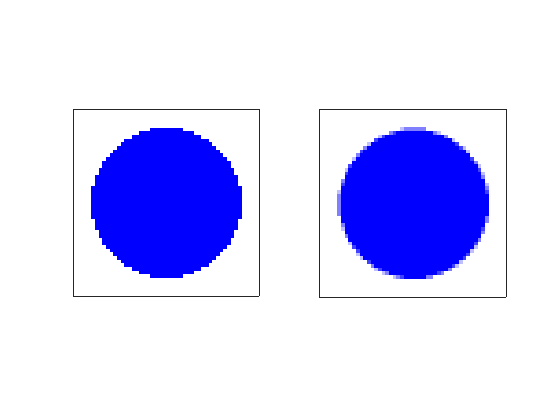

clear

% Raster parameters
Nx = 51;
Ny = 51;
img = 255 * ones(Ny, Nx, 3);
super = 255 * ones(2 * Ny, 2 * Nx, 3);

% Circle parameters
cx = round(Nx / 2);
cy = round(Ny / 2);
r = 20;
colour = [0, 0, 255];

% Draw filled circle
img = drawcircle(img, cx, cy, r, colour);
img = floodfill(img, cx, cy, [255 ; 255 ; 255], colour);

% Apply antialiasing
super = drawcircle(super, 2*cx, 2*cy, 2*r, colour);
super = floodfill(super, 2*cx, 2*cy, [255 ; 255 ; 255], colour);

i = 1 : Ny;
j = 1 : Nx;
imgaa(i, j, :) = uint8((super(2*i-1,2*j-1,:) + super(2*i,2*j-1,:) + super(2*i-1,2*j,:) + super(2*i,2*j,:)) / 4);

% Plot images
figure
subplot(1, 2, 1)
image(img)
xticks([]);
yticks([]);
axis equal tight

subplot(1, 2, 2)
image(imgaa)
xticks([]);
yticks([]);
axis equal tight

### Gaussian blur

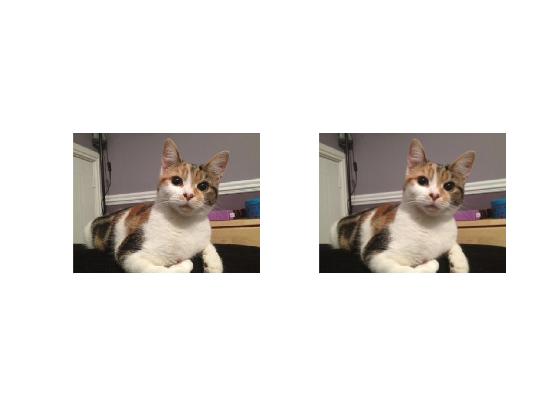

clear

% Download and read image file
urlwrite('https://github.com/jonshiach/graphics-book/raw/main/images/cavendish.jpg','cavendish.jpg');
img = imread('cavendish.jpg');

% Calculate kernel filter
n = 5;
x = -floor(n / 2) : floor(n / 2);
sigma = 1;
gaussian = 1 / sqrt(2 * pi * sigma^2) * exp(- x.^2 / (2 * sigma^2));
K = gaussian' * gaussian;
K = K ./ K(1,1);
K = K ./ sum(sum(K));

% Apply kernel
img_blur = img;
for i = 1 : 3
    img_blur(:,:,i) = conv2(img(:,:,i), K, 'same');
end

% Plot images
subplot(1, 2, 1)
image(img)
axis equal tight off
axis([0, size(img,2), 0, size(img,1)])

subplot(1, 2, 2)
image(img_blur)
axis equal tight off
axis([0, size(img,2), 0, size(img,1)])

### Unsharp masking

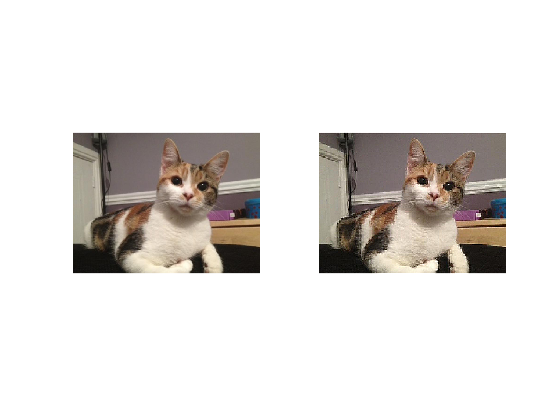

% Sharpen kernel
K = [0, -1, 0 ; -1, 5, -1 ; 0, -1, 0];

% Apply kernel
img_sharpen = img;
for i = 1 : 3
    img_sharpen(:,:,i) = conv2(img(:,:,i), K, 'same');
end

% Plot images
figure
subplot(1, 2, 1)
image(img)
axis equal tight off

subplot(1, 2, 2)
image(img_sharpen)
axis equal tight off

## Functions

### Pixel grid

Function to plot a grid of lines for the pixels

function pixelgrid(img)

[Ny, Nx, ~] = size(img);
for i = 1 : Ny + 1
    yline(i-0.5, Color='k', LineWidth=1)
end
for i = 1 : Nx + 1
    xline(i-0.5, Color='k', LineWidth=1)
end

end

### Basic Bresenham algorithm

function R = bresenham(R, x0, y0, x1, y1, colour)

x = x0;
y = y0;
dx = x1 - x0;
dy = y1 - y0;
d = 2 * dy - dx;
 
while true
    R(y, x, :) = colour;
    if x == x1 && y == y1
        return
    end
    if d <= 0
        d = d + 2 * dy;
    else
        y = y + 1;
        d = d + 2 * dy - 2 * dx;
    end
    x = x + 1;
end

end

### Modified Bresenham algorithm

function R = drawline(R, x0, y0, x1, y1, colour)

x = x0;
y = y0;
dx = abs(x1 - x0);
dy = abs(y1 - y0);
d = 2 * dx - 2 * dy;
xstep = 1;
ystep = 1;
if x > x1
    xstep = -1;
end
if y > y1
    ystep = -1;
end

while true
    R(y, x, :) = colour;
    if x == x1 && y == y1
        return
    end

    dd = 0;
    if d >= -dy
        x = x + xstep;
        dd = dd - 2 * dy;
    end
    
    if d <= dx
        y = y + ystep;
        dd = dd + 2 * dx;
    end
    d = d + dd;
end

end

### Midpoint algorithm

function R = drawcircle(R, cx, cy, r, colour)

x = r;
y = 0;
d = 1 - r;
while x >= y
    R(cx + x,cy + y, :) = colour;
    R(cx + x,cy - y, :) = colour;
    R(cx - x,cy + y, :) = colour;
    R(cx - x,cy - y, :) = colour;
    R(cx + y,cy + x, :) = colour;
    R(cx + y,cy - x, :) = colour;
    R(cx - y,cy + x, :) = colour;
    R(cx - y,cy - x, :) = colour;

    if d <= 0
        d = d + 2 * y + 3;
    else
        d = d + 2 * y - 2 * x + 5;
        x = x - 1;
    end
    y = y + 1;
end

end

### Flood fill algorithm

function R = floodfill(R, x0, y0, target, replacement)

Q = [x0, y0];
while isempty(Q) == 0
    x = Q(end,1);
    y = Q(end,2);
    Q(end, :) = [];
    if isequal([R(y,x,1) ; R(y,x,2) ; R(y,x,3)], target)
        R(y,x,:) = replacement;
        Q = [ Q ; x + 1, y ; x - 1, y ; x, y + 1 ; x, y - 1 ];
    end
end

end

### Scanline algorithm polygon

function R = drawpolygon(R, X, Y, colour)

% Generate edge table
n = length(X);
ET = [];
for i = 1 : n
    j = 1 + mod(i, n);
    if Y(i) < Y(j)
        ET = [ET ; X(i), (X(j) - X(i)) / (Y(j) - Y(i)), Y(i), Y(j) ];
    elseif Y(i) > Y(j)
        ET = [ET ; X(j), (X(i) - X(j)) / (Y(i) - Y(j)), Y(j), Y(i) ];
    else
        continue
    end
end

% Loop through scanlines
y = min(Y);
AET = [];
while ~isempty(ET) || ~isempty(AET)
    
    % Move edges from ET to AET whose ymin = y
    i = 1;
    while i <= size(ET,1)
        if ET(i,3) == y
            AET = [ AET ; ET(i,[1,2,4]) ];
            ET(i,:) = [];
        else
            i = i + 1;
        end
    end

    % Sort AET by x value
    AET = sortrows(AET, 1);

    % Fill scanline
    i = 1;
    while i < size(AET,1)
        xL = ceil(round(AET(i,1),2));
        xR = floor(round(AET(i+1,1),2));
        if xL == xR
            R(y,xL,:) = colour;
            i = i + 1;
        else
            for x = xL : xR
                R(y,x,:) = colour;
            end
            i = i + 2;
        end
    end

    % Remove edges from AET whose ymax = y
    i = 1;
    while i <= size(AET,1)
        if AET(i,3) == y
            AET(i,:) = [];
        else
            i = i + 1;
        end 
    end

    % Add 1/m to x in AET
    AET(:,1) = AET(:,1) + AET(:,2);

    % Increment y
    y = y + 1;

end

end